# Basketball Player Positions

Find natural groupings in basketball player data based on height, weight, and various statistics per game.

#### Import data

Read file of basketball player data containing per game statistics.

data = readtable("basketballDataProcessed.csv");
posnames = ["G","G-F","F-G","F","F-C","C-F","C"];
data.pos = categorical(data.pos,posnames);

Extract numeric data (and their names) and normalize data to mean 0 and standard deviation 1. Set random seed. 

labels = data.Properties.VariableNames(4:end);
stats = data{:,4:end};
statsNorm = normalize(stats);
rng(0)

## Dimensionality Reduction

Perform multidimensional scaling

d = pdist(statsNorm);
[X,e] = cmdscale(d);

Perform PCA

[pcs,scrs,~,~,pexp] = pca(statsNorm);

Compare PCA and CMD scaling

Note that CMD scaling is the same as PCA when using the 2-norm as the distance metric (within a potential minus sign). In this case, it turns out that the 3rd component is flipped:

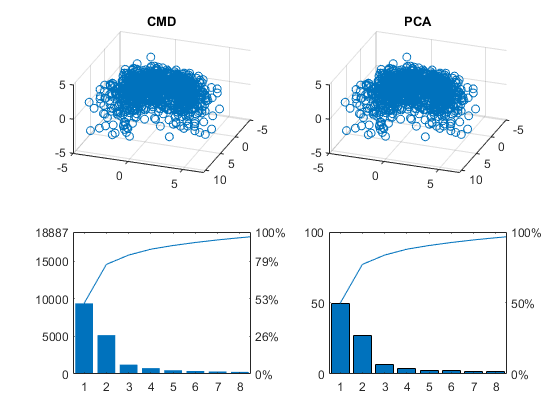

clf
tiledlayout(2,2);

% CMD scatter
nexttile
scatter3(X(:,1),X(:,2),-X(:,3))   % flip 3rd component
view(110,40)
title("CMD")

% PCA scatter
nexttile
scatter3(scrs(:,1),scrs(:,2),scrs(:,3))
view(110,40)
title("PCA")

% CMD pareto
nexttile
pareto(e)

% PCA pareto
nexttile
pareto(pexp)

Look for correlation with player position

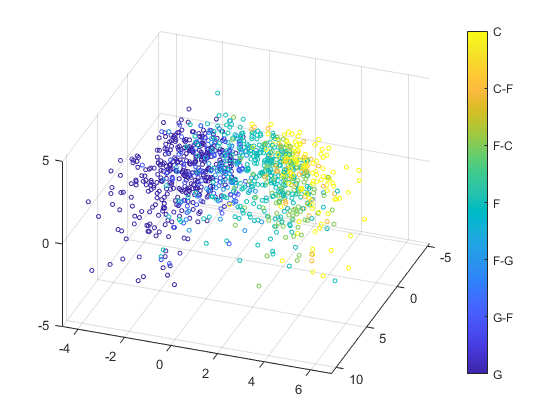

clf
scatter3(scrs(:,1),scrs(:,2),scrs(:,3),10,data.pos)
view(110,40)
c = colorbar;
c.TickLabels = posnames;

## Clustering Algorithms

Cluster data into *k* groups using different methods and plot transformed (PCA) data by group for each method.

rng(0)
k = 2

k = 2

Perform k-means clustering

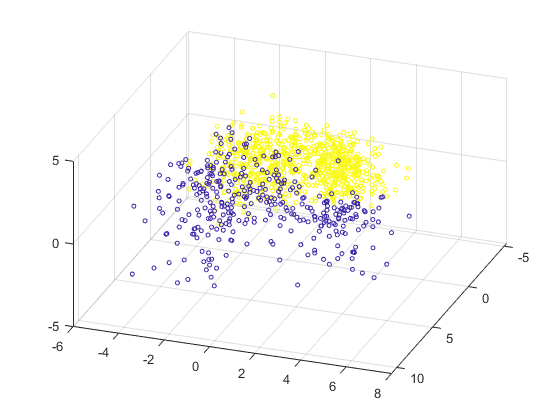

grpKM = kmeans(statsNorm,k,"Replicates",5);
scatter3(scrs(:,1),scrs(:,2),scrs(:,3),10,grpKM)
view(110,40)

Perform hierarchical clustering

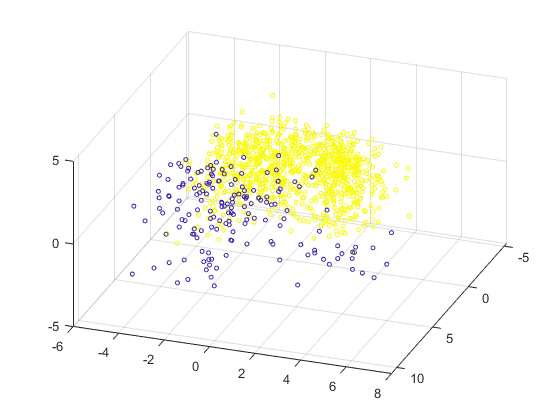

Z = linkage(statsNorm,"ward");
grpHC = cluster(Z,"maxclust",k);
scatter3(scrs(:,1),scrs(:,2),scrs(:,3),10,grpHC)
view(110,40)

Fit a Gaussian mixture model

gmModel = fitgmdist(statsNorm,k,"Replicates",5,"RegularizationValue",0.02);

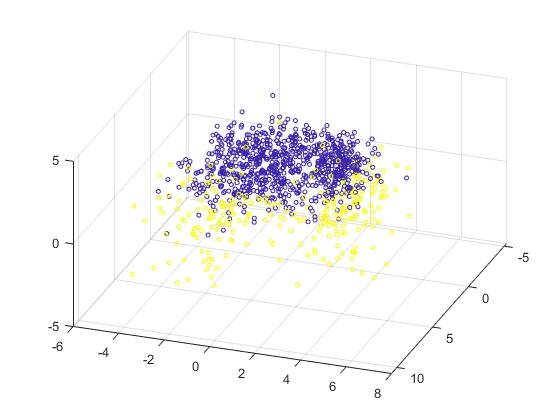

grpGM = cluster(gmModel,statsNorm);
scatter3(scrs(:,1),scrs(:,2),scrs(:,3),10,grpGM)
view(110,40)

## Interpret Clusters

Visualize group separation for GMM.

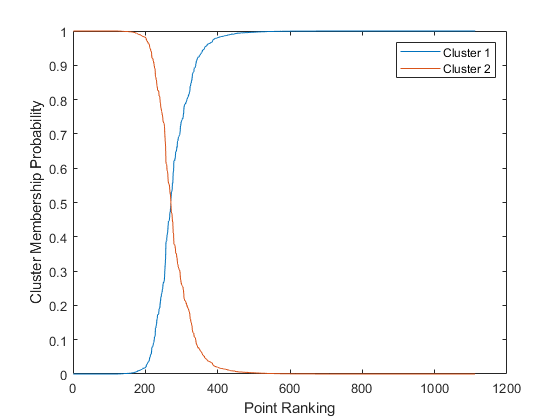

[grpGM,~,gprob] = cluster(gmModel,statsNorm);
gpsort = sortrows(gprob,1:k-1);
plot(gpsort)
xlabel("Point Ranking")
ylabel("Cluster Membership Probability")
legend("Cluster "+ (1:k))

Create a silhouette plot

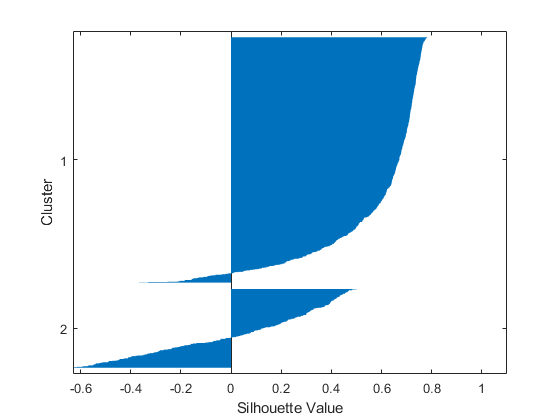

silhouette(statsNorm,grpGM)

Visualize cluster membership by position.

ct = crosstab(data.pos,grpGM)

ct =    297    70
    81    18
    40     9
   247    69
    70    48
    29    15
    78    41


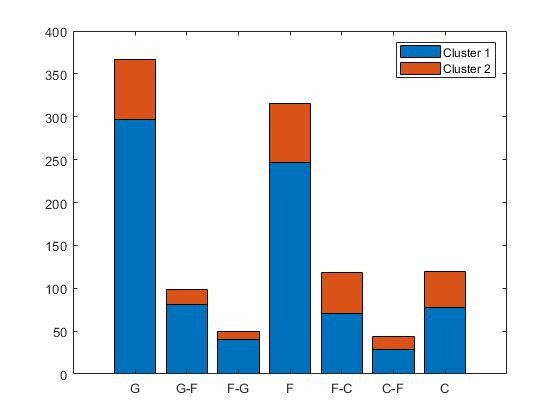

bar(ct,"stacked")
legend("Cluster "+ (1:k))
xticklabels(categories(data.pos))

Create parallel coordinates plot of group mean.

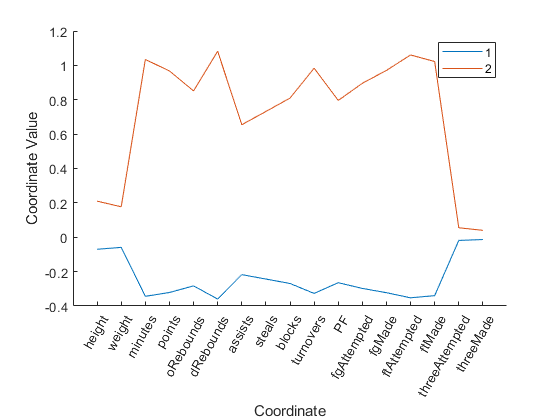

parallelcoords(gmModel.mu,"Group",1:k)
xticklabels(labels)
xtickangle(60)

Evaluate optimal number of clusters

cev = evalclusters(statsNorm,"gmdistribution","DaviesBouldin","KList",2:6)

cev =   DaviesBouldinEvaluation with properties:

    NumObservations: 1112
         InspectedK: [2 3 4 5 6]
    CriterionValues: [1.6949 1.4852 1.6345 1.8583 1.5947]
           OptimalK: 3


optK = cev.OptimalK

optK = 3

## Clusters within a Player Position

Extracts the data for the guard position (`G`). Can change to other positions.

posStats = statsNorm(data.pos == "G",:);

Create and visualize hierarchical tree.

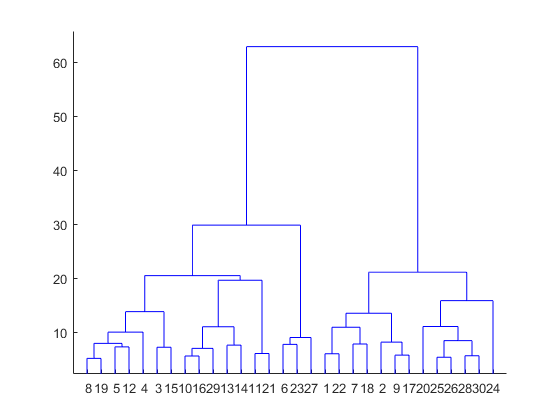

Z = linkage(posStats,"ward");
dendrogram(Z)

Cluster into 2 and 3 clusters.

gc2 = cluster(Z,"maxclust",2);
gc3 = cluster(Z,"maxclust",3);

Visualize clusters (middle 50% of each cluster)

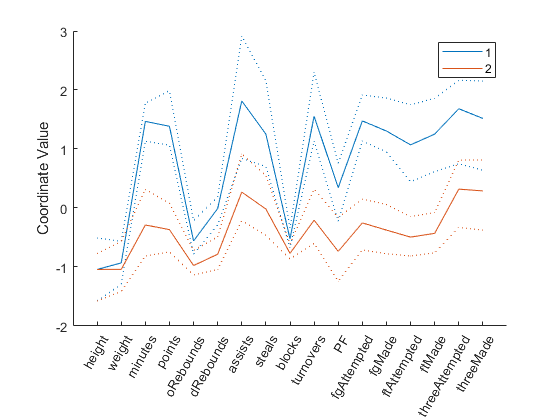

parallelcoords(posStats,"Group",gc2,"Quantile",0.25,"Labels",labels)
xtickangle(60)

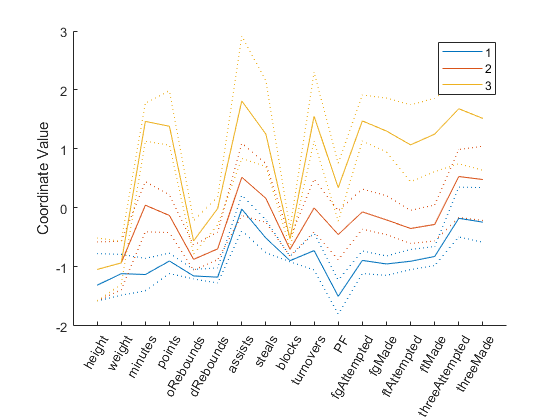

parallelcoords(posStats,"Group",gc3,"Quantile",0.25,"Labels",labels)
xtickangle(60)

Evaluate optimal number of clusters.

ec = evalclusters(posStats,"linkage","silhouette","KList",2:8)

ec =   SilhouetteEvaluation with properties:

    NumObservations: 367
         InspectedK: [2 3 4 5 6 7 8]
    CriterionValues: [0.6281 0.2870 0.2611 0.2034 0.2294 0.2390 0.2299]
           OptimalK: 2
